clear;clc;filled_data=readtable('filled_data.csv');raw_data=readtable("data_cleared.csv")

raw_data = 7700×6 table
           Var1                 rev_time                time          place_id    user    capacity
    ___________________    ___________________    ________________    ________    ____    ________

    2017-06-04 07:00:00    2017-06-04 07:00:00    04.06.2017 07:59       0        204       2813  
    2017-06-04 08:00:00    2017-06-04 08:00:00    04.06.2017 08:59       0        332       2813  
    2017-06-04 09:00:00    2017-06-04 09:00:00    04.06.2017 09:59       0        485       2813  
    2017-06-04 10:00:00    2017-06-04 10:00:00    04.06.2017 10:59       0        583       2813  
    2017-06-04 11:00:00    2017-06-04 11:00:00    04.06.2017 11:59       0        614       2813  
    2017-06-04 12:00:00    2017-06-04 12:00:00    04.06.2017 12:29       0    

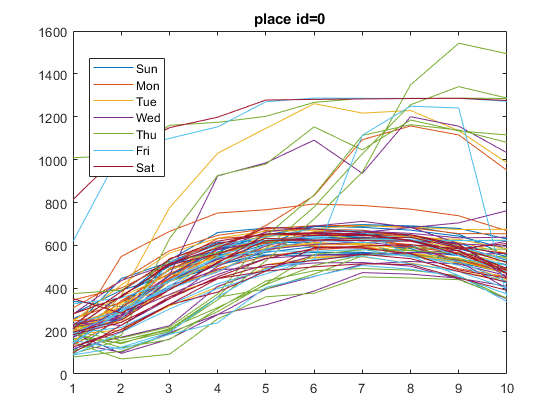

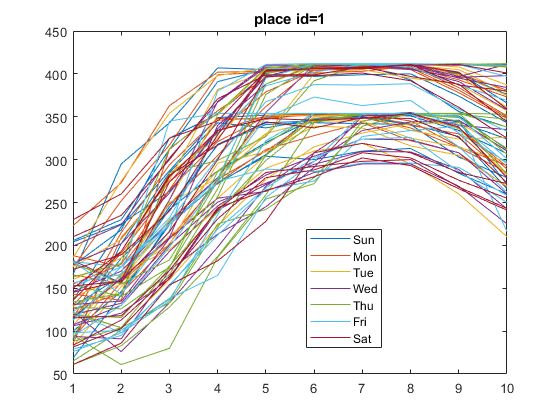

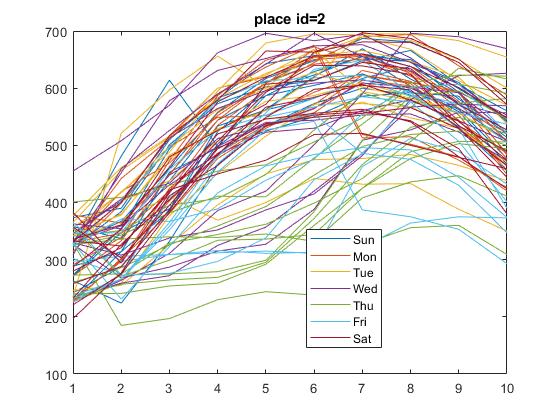

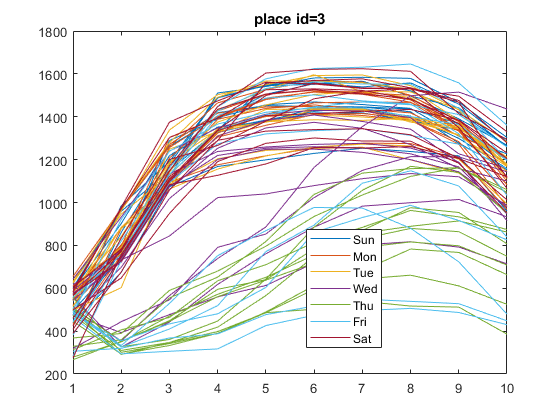

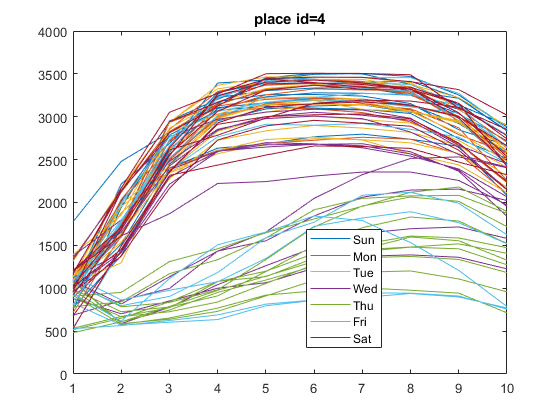

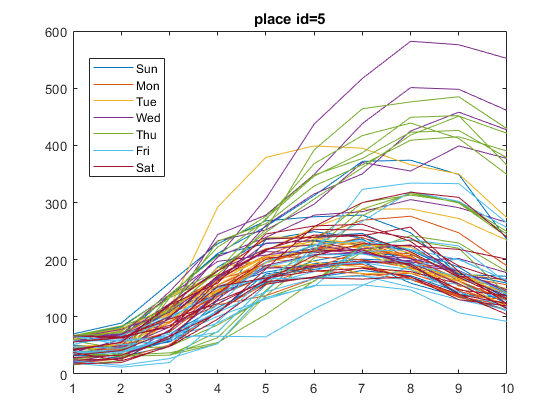

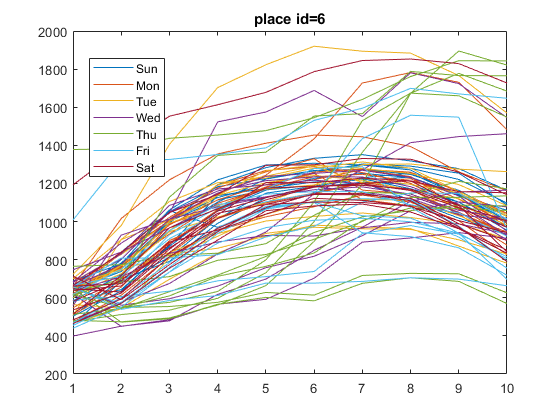

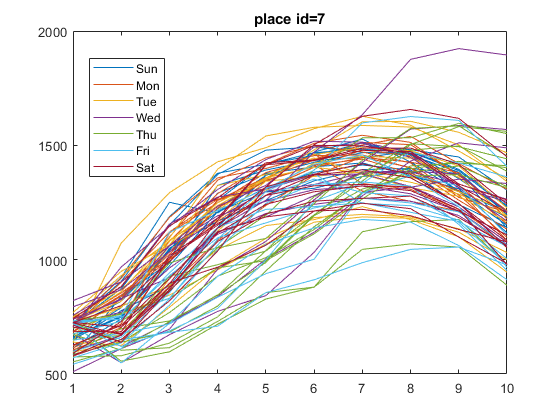

seperated={};
for  i=0:9
    seperated{i+1,1}=i;
    seperated{i+1,2}=filled_data(filled_data.place_id==i,:);
    ddate=(datetime(filled_data{filled_data.place_id==i,1}, 'InputFormat','yyyy-mm-dd HH:mm:ss', 'Format','dd-MMM-yyyy'));
    temp1=reshape(ddate,10,[]);
    temp2=reshape(filled_data.user(filled_data.place_id==i,1),10,[]);
    seperated{i+1,3}=[datenum(temp1(1,:));temp2];
    seperated{i+1,4}=raw_data.user(filled_data.place_id==i);
end

for i=0:9
    g=seperated{i+1,3};
    [dayno,dayName]=weekday(g(1,:));
    figure(i+1)
    ha=plot(g(2:end,dayno==1),'Color',[0 0.4470 0.7410]);hold on;
    hb=plot(g(2:end,dayno==2),'Color',[0.8500 0.3250 0.0980]);
    hc=plot(g(2:end,dayno==3),'Color',[0.9290 0.6940 0.1250]);
    hd=plot(g(2:end,dayno==4),'Color',[0.4940 0.1840 0.5560]);
    he=plot(g(2:end,dayno==5),'Color',[0.4660 0.6740 0.1880]);
    hf=plot(g(2:end,dayno==6),'Color',[0.3010 0.7450 0.9330]);
    hg=plot(g(2:end,dayno==7),'Color',[0.6350 0.0780 0.1840]);
    legend([ha(1),hb(1),hc(1),hd(1),he(1),hf(1),hg(1)],'Sun','Mon','Tue','Wed','Thu','Fri','Sat','Location',"best")
    title(strcat('place id=',num2str(i)))
    hold off
end

g1 =    204
   332
   485
   583
   614
   613
   605
   585
   520
   470


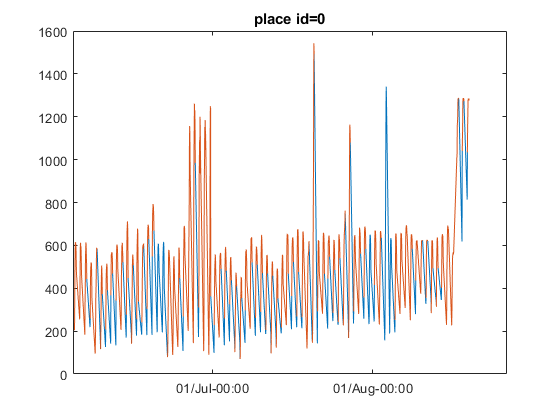

g1 =    129
   164
   245
   317
   341
   343
   342
   341
   303
   279


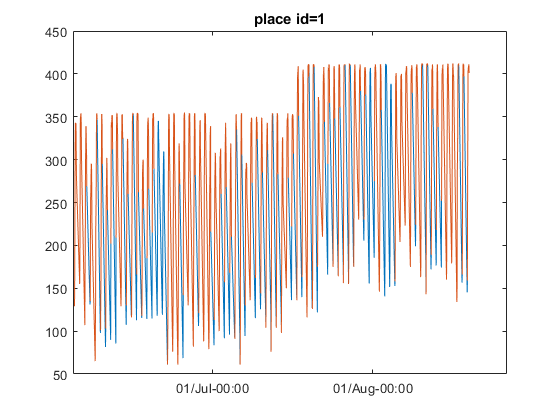

g1 =    273
   355
   494
   582
   643
   657
   660
   646
   581
   520


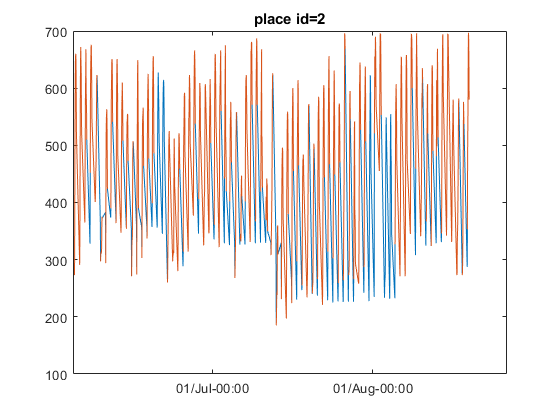

g1 =          623
         967
        1263
        1396
        1456
        1469
        1457
        1439
        1309
        1227


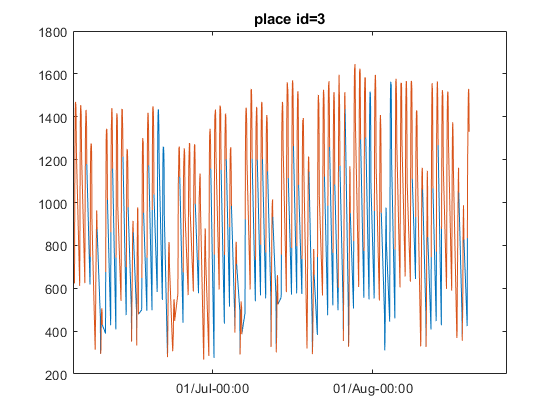

g1 =         1090
        2016
        2811
        3178
        3257
        3260
        3241
        3154
        2848
        2665


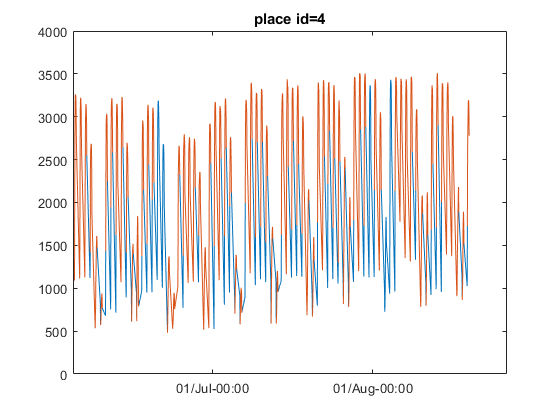

g1 =     70
    89
   159
   228
   268
   275
   278
   247
   174
   171


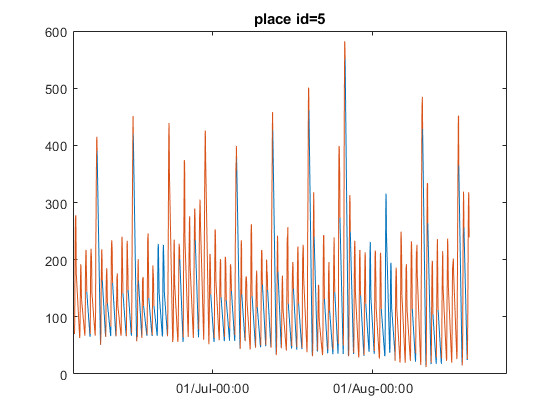

g1 =          597
         801
        1061
        1219
        1297
        1306
        1297
        1271
        1136
        1028


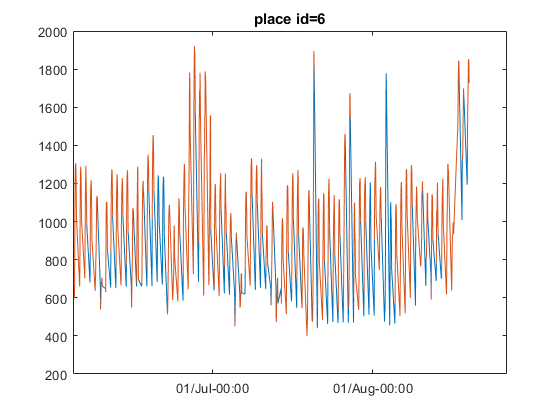

g1 =          718
         873
        1151
        1373
        1479
        1493
        1470
        1461
        1297
        1184


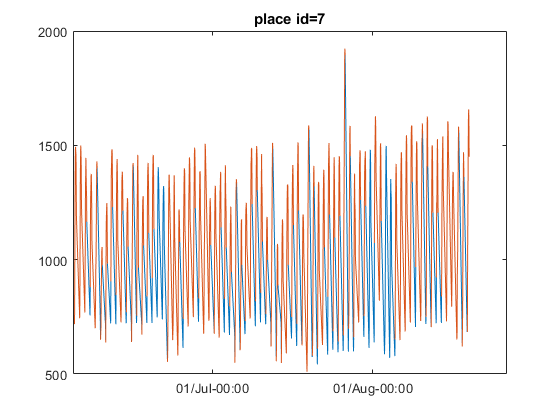

g1 =          556
         857
        1172
        1363
        1399
        1406
        1376
        1361
        1222
        1130


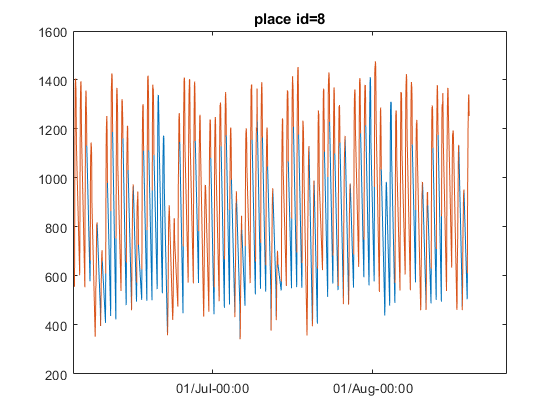

g1 =    454
   527
   666
   800
   845
   845
   820
   824
   725
   673


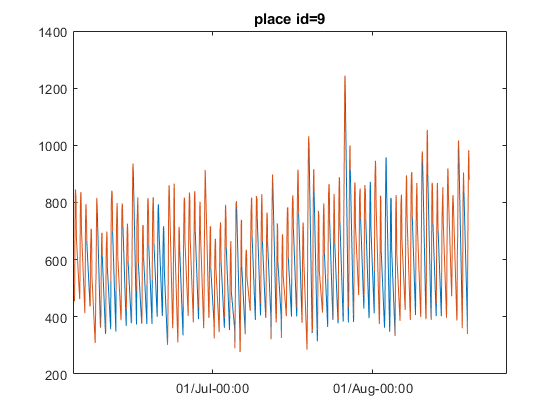


for i=0:9
g=seperated{i+1,2};
g1=seperated{i+1,4}
figure((i+1)*2)
plot(g.Var1,g.user);hold on;plot(g.Var1,g1);datetick('x','dd/mmm-HH:MM',"keeplimits","keeplimits")
title(strcat('place id=',  num2str(i)))
end

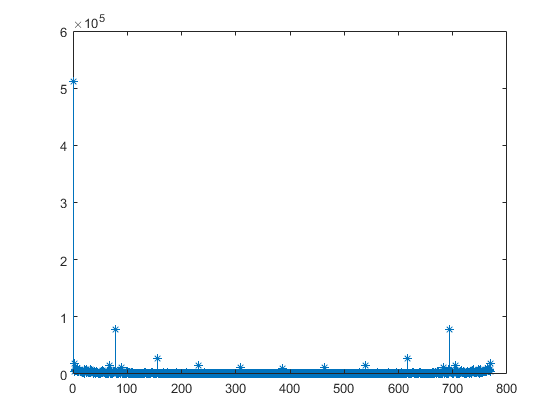


g_ft=fft(g.user);
g_ifft=ifft(g_ft);
figure()
stem(abs(g_ft),'*');

result1 = 	1.0e+03 *

         0    3.7786    3.5190


results =          0   32.2158   18.0875   30.6666   21.8258


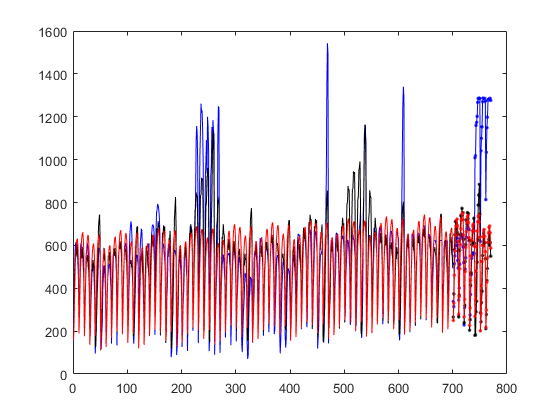

result1 = 	1.0e+03 *

         0    3.7786    3.5190
    0.0010    0.2291    0.2277


results =          0   32.2158   18.0875   30.6666   21.8258
    1.0000    8.3123   11.5044    8.1375   12.4877


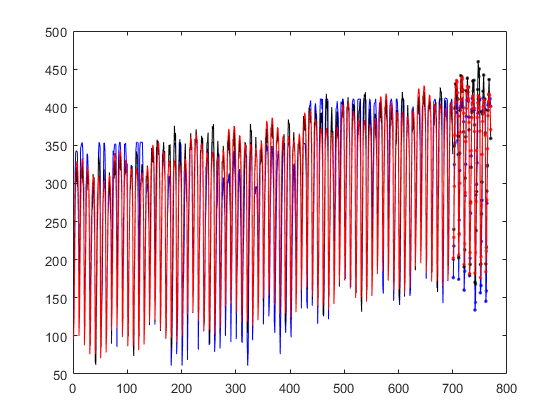

result1 = 	1.0e+03 *

         0    3.7786    3.5190
    0.0010    0.2291    0.2277
    0.0020    0.6909    0.5911


results =          0   32.2158   18.0875   30.6666   21.8258
    1.0000    8.3123   11.5044    8.1375   12.4877
    2.0000   12.8984   11.7355   10.8901   13.9820


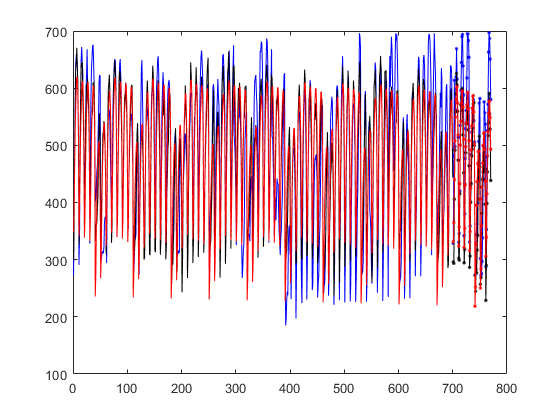

result1 = 	1.0e+03 *

         0    3.7786    3.5190
    0.0010    0.2291    0.2277
    0.0020    0.6909    0.5911
    0.0030    1.4685    1.6651


results =          0   32.2158   18.0875   30.6666   21.8258
    1.0000    8.3123   11.5044    8.1375   12.4877
    2.0000   12.8984   11.7355   10.8901   13.9820
    3.0000   16.8252   15.8735   19.1252   19.1567


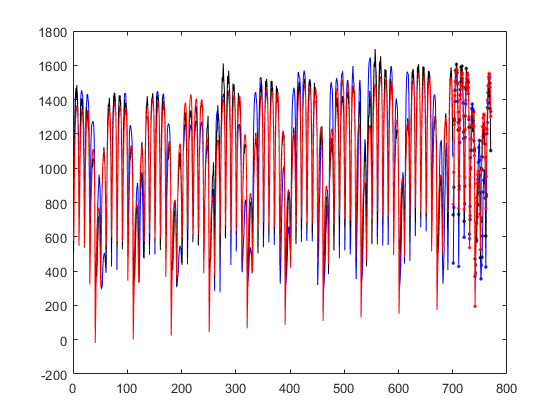

result1 = 	1.0e+03 *

         0    3.7786    3.5190
    0.0010    0.2291    0.2277
    0.0020    0.6909    0.5911
    0.0030    1.4685    1.6651
    0.0040    3.3795    3.9636


results =          0   32.2158   18.0875   30.6666   21.8258
    1.0000    8.3123   11.5044    8.1375   12.4877
    2.0000   12.8984   11.7355   10.8901   13.9820
    3.0000   16.8252   15.8735   19.1252   19.1567
    4.0000   17.1038   18.4323   21.2228   23.4239


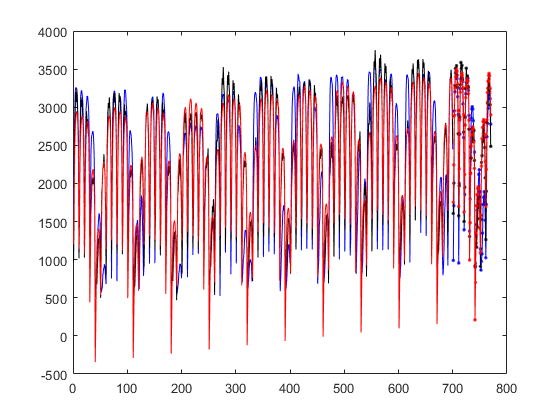

result1 = 	1.0e+03 *

         0    3.7786    3.5190
    0.0010    0.2291    0.2277
    0.0020    0.6909    0.5911
    0.0030    1.4685    1.6651
    0.0040    3.3795    3.9636
    0.0050    0.4655    0.5124


results =          0   32.2158   18.0875   30.6666   21.8258
    1.0000    8.3123   11.5044    8.1375   12.4877
    2.0000   12.8984   11.7355   10.8901   13.9820
    3.0000   16.8252   15.8735   19.1252   19.1567
    4.0000   17.1038   18.4323   21.2228   23.4239
    5.0000   35.0740   23.8894   38.9055   33.7855


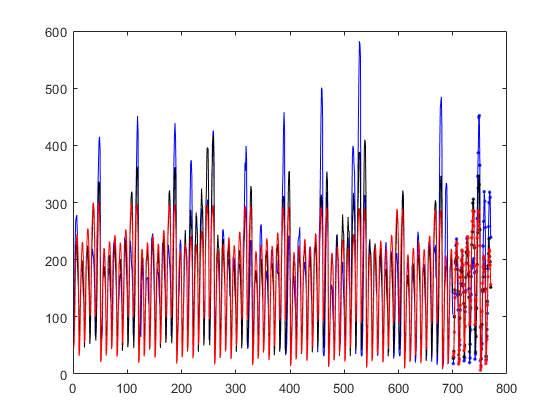

result1 = 	1.0e+03 *

         0    3.7786    3.5190
    0.0010    0.2291    0.2277
    0.0020    0.6909    0.5911
    0.0030    1.4685    1.6651
    0.0040    3.3795    3.9636
    0.0050    0.4655    0.5124
    0.0060    4.2397    3.7687


results =          0   32.2158   18.0875   30.6666   21.8258
    1.0000    8.3123   11.5044    8.1375   12.4877
    2.0000   12.8984   11.7355   10.8901   13.9820
    3.0000   16.8252   15.8735   19.1252   19.1567
    4.0000   17.1038   18.4323   21.2228   23.4239
    5.0000   35.0740   23.8894   38.9055   33.7855
    6.0000   26.3232   12.1580   22.8506   14.4704


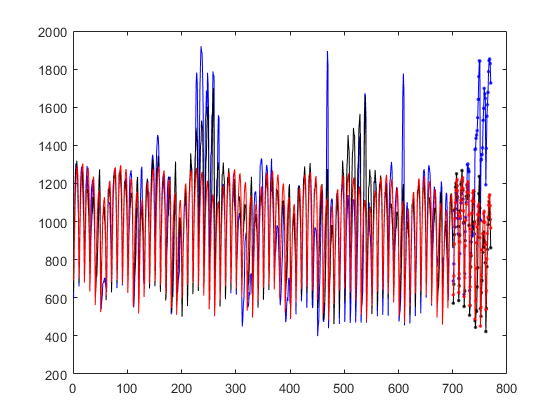

result1 = 	1.0e+03 *

         0    3.7786    3.5190
    0.0010    0.2291    0.2277
    0.0020    0.6909    0.5911
    0.0030    1.4685    1.6651
    0.0040    3.3795    3.9636
    0.0050    0.4655    0.5124
    0.0060    4.2397    3.7687
    0.0070    1.1167    1.0651


results =          0   32.2158   18.0875   30.6666   21.8258
    1.0000    8.3123   11.5044    8.1375   12.4877
    2.0000   12.8984   11.7355   10.8901   13.9820
    3.0000   16.8252   15.8735   19.1252   19.1567
    4.0000   17.1038   18.4323   21.2228   23.4239
    5.0000   35.0740   23.8894   38.9055   33.7855
    6.0000   26.3232   12.1580   22.8506   14.4704
    7.0000    8.2488    8.4545    7.6732    9.7018


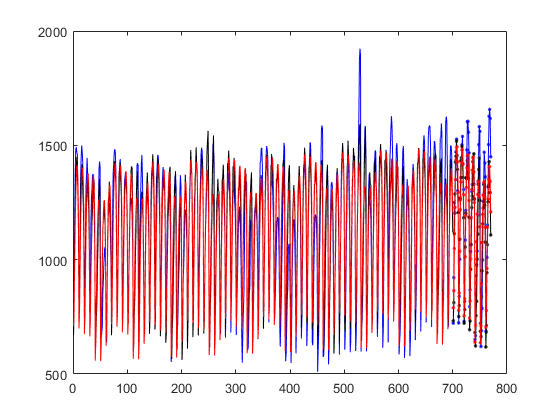

result1 = 	1.0e+03 *

         0    3.7786    3.5190
    0.0010    0.2291    0.2277
    0.0020    0.6909    0.5911
    0.0030    1.4685    1.6651
    0.0040    3.3795    3.9636
    0.0050    0.4655    0.5124
    0.0060    4.2397    3.7687
    0.0070    1.1167    1.0651
    0.0080    1.0399    1.1696


results =          0   32.2158   18.0875   30.6666   21.8258
    1.0000    8.3123   11.5044    8.1375   12.4877
    2.0000   12.8984   11.7355   10.8901   13.9820
    3.0000   16.8252   15.8735   19.1252   19.1567
    4.0000   17.1038   18.4323   21.2228   23.4239
    5.0000   35.0740   23.8894   38.9055   33.7855
    6.0000   26.3232   12.1580   22.8506   14.4704
    7.0000    8.2488    8.4545    7.6732    9.7018
    8.0000   11.7038   10.2577   13.4552   12.9803


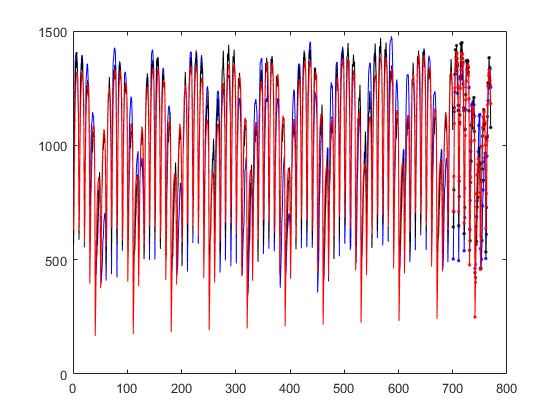

result1 = 	1.0e+03 *

         0    3.7786    3.5190
    0.0010    0.2291    0.2277
    0.0020    0.6909    0.5911
    0.0030    1.4685    1.6651
    0.0040    3.3795    3.9636
    0.0050    0.4655    0.5124
    0.0060    4.2397    3.7687
    0.0070    1.1167    1.0651
    0.0080    1.0399    1.1696
    0.0090    0.6438    0.6381


results =          0   32.2158   18.0875   30.6666   21.8258
    1.0000    8.3123   11.5044    8.1375   12.4877
    2.0000   12.8984   11.7355   10.8901   13.9820
    3.0000   16.8252   15.8735   19.1252   19.1567
    4.0000   17.1038   18.4323   21.2228   23.4239
    5.0000   35.0740   23.8894   38.9055   33.7855
    6.0000   26.3232   12.1580   22.8506   14.4704
    7.0000    8.2488    8.4545    7.6732    9.7018
    8.0000   11.7038   10.2577   13.4552   12.9803
    9.0000    8.7840    8.7237    8.6593   10.0065


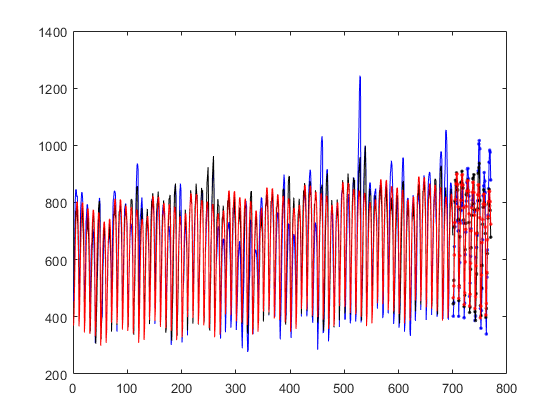

results=[];result1=[];
for i=0:9
N=770;
% Define regressors
t0=ones(N,1);t1=(1:N)';
% Harmonics of month
%T= 1 ay = 30 days*10 hours
Tay=28*10;omy=2*pi/(Tay);
s1=sin(1*omy*t1);c1=cos(1*omy*t1);s2=sin(2*omy*t1);c2=cos(2*omy*t1);
s3=sin(3*omy*t1);c3=cos(3*omy*t1);
% s5=sin(5*om*t1);c5=cos(5*om*t1);
% s6=sin(6*om*t1);c6=cos(6*om*t1);s7=sin(7*om*t1);c7=cos(7*om*t1);
% s9=sin(9*om*t1);c9=cos(9*om*t1);s10=sin(10*om*t1);c10=cos(10*om*t1)
% s11=sin(11*om*t1);c11=cos(11*om*t1);s13=sin(13*om*t1);c13=cos(13*om*t1);
% s14=sin(14*om*t1);c14=cos(14*om*t1);s15=sin(15*om*t1);c15=cos(15*om*t1);
% s17=sin(17*om*t1);c17=cos(17*om*t1);s18=sin(18*om*t1);c18=cos(18*om*t1);
% s19=sin(19*om*t1);c19=cos(19*om*t1);s21=sin(21*om*t1);c21=cos(21*om*t1);
% s22=sin(22*om*t1);c22=cos(22*om*t1);s23=sin(23*om*t1);c23=cos(23*om*t1);
% s25=sin(25*om*t1);c25=cos(25*om*t1);s26=sin(26*om*t1);c26=cos(26*om*t1);
% s27=sin(27*om*t1);c27=cos(27*om*t1);
%s4=sin(4*om*t1);c4=cos(4*om*t1); s8=sin(8*om*t1);c8=cos(8*om*t1);
%s12=sin(12*om*t1);c12=cos(12*om*t1); s16=sin(16*om*t1);c12=cos(16*om*t1);
% Harmonics of 1 week %Tgun= 10 hours
Thafta=10*7;omh=2*pi/Thafta;
sh1=sin(1*omh*t1);ch1=cos(1*omh*t1);sh2=sin(2*omh*t1);ch2=cos(2*omh*t1);
sh3=sin(3*omh*t1);ch3=cos(3*omh*t1);sh4=sin(4*omh*t1);ch4=cos(4*omh*t1);
sh5=sin(5*omh*t1);ch5=cos(5*omh*t1);sh6=sin(6*omh*t1);ch6=cos(6*omh*t1);
sh8=sin(8*omh*t1);ch8=cos(8*omh*t1);sh9=sin(9*omh*t1);ch9=cos(9*omh*t1);
sh10=sin(10*omh*t1);ch10=cos(10*omh*t1);sh11=sin(11*omh*t1);ch11=cos(11*omh*t1);
sh12=sin(12*omh*t1);ch12=cos(12*omh*t1);sh13=sin(13*omh*t1);ch13=cos(13*omh*t1);
sh15=sin(15*omh*t1);ch15=cos(15*omh*t1);sh16=sin(16*omh*t1);ch16=cos(16*omh*t1);
sh17=sin(17*omh*t1);ch17=cos(17*omh*t1);sh18=sin(18*omh*t1);ch18=cos(18*omh*t1);
sh19=sin(19*omh*t1);ch19=cos(19*omh*t1);sh20=sin(20*omh*t1);ch20=cos(20*omh*t1);
sh22=sin(22*omh*t1);ch22=cos(22*omh*t1);sh23=sin(23*omh*t1);ch23=cos(23*omh*t1);
sh24=sin(24*omh*t1);ch24=cos(24*omh*t1);sh25=sin(25*omh*t1);ch25=cos(25*omh*t1);
sh26=sin(26*omh*t1);ch26=cos(26*omh*t1);sh27=sin(27*omh*t1);ch27=cos(27*omh*t1);
% Harmonics of 1 gun
Tgun=10;omd=2*pi/Tgun;
sd1=sin(omd*t1);cd1=cos(omd*t1);sd2=sin(2*omd*t1);cd2=cos(2*omd*t1);
sd3=sin(3*omd*t1);cd3=cos(3*omd*t1);sd4=sin(4*omd*t1);cd4=cos(4*omd*t1);
sd5=sin(5*omd*t1);cd5=cos(5*omd*t1);sd6=sin(6*omd*t1);cd6=cos(6*omd*t1);
%include modulation
 FFour=[s1 c1 s2 c2 s3 c3 sh1 ch1 sh2 ch2...
        sh3 ch3 sh4 ch4 sh5 ch5 sh6 ch6 sh8 ch8...
        sh9 ch9 sh10 ch10 sh11 ch11 sh12 ch12 sh13 ch13 ...
        sd1 cd1 sd2 cd2 sd3 cd3 sd4 cd4...
        s1.*sd1 c1.*sd1 s1.*cd1 c1.*cd1...
        s1.*sd2 c1.*sd2 s1.*cd2 c1.*cd2...
        s1.*sd3 c1.*sd3 s1.*cd3 c1.*cd3...
        s1.*sd4 c1.*sd4 s1.*cd4 c1.*cd4...
        s2.*sd1 c2.*sd1 s2.*cd1 c2.*cd1...
        s2.*sd2 c2.*sd2 s2.*cd2 c2.*cd2...
        s2.*sd3 c2.*sd3 s2.*cd3 c2.*cd3...
        s2.*sd4 c2.*sd4 s2.*cd4 c2.*cd4...
        s3.*sd1 c3.*sd1 s3.*cd1 c3.*cd1...
        s3.*sd2 c3.*sd2 s3.*cd2 c3.*cd2...
        s3.*sd3 c3.*sd3 s3.*cd3 c3.*cd3...
        s3.*sd4 c3.*sd4 s3.*cd4 c3.*cd4...
       ];
 
 Ftotal=[t0 t1 FFour];
     %training_data=
     n=770-70*1;   
     FM=Ftotal(1:n,:); % fourier for base horizon
     S=seperated{i+1,2}.user;
     Shorizon=S(1:n,:); % Base Actual Data
     Stest=S(n+1:n+70,:);
     FT=Ftotal(n+1:n+70,:); %Fourier for test horizon
     test_coeff=(FM'*FM)^(-1)*FM'*Shorizon;
     model_fit=FM*test_coeff;
     test=FT*test_coeff;
     fark_fline=Stest-test;
     MSE=sqrt(fark_fline'*fark_fline);
     MAPE=mean(abs(fark_fline./Stest))*100;
     fark_fline1=model_fit-Shorizon;
     MAPE_mod=mean(abs(fark_fline1./Shorizon))*100;       

hours=repmat(eye(10),77,1);
a=[ones(10,1) zeros(10,6)];
a=[a;circshift(a,1,2);circshift(a,2,2);circshift(a,3,2);circshift(a,4,2);circshift(a,5,2);circshift(a,6,2)];
week=repmat(a,11,1);
hours=hours(:,1:end-1);week=week(:,1:end-1);
Freg=[t0,t1,hours,week];
     
     FM=Freg(1:n,:); % fourier for base horizon
     Shorizon=S(1:n,:); % Base Actual Data
     Stest=S(n+1:n+70,:);
     FT=Freg(n+1:n+70,:); %Fourier for forecast horizon
     test_coeff_reg=(FM'*FM)^(-1)*FM'*Shorizon;
     model_fit_reg=FM*test_coeff_reg;
     test_reg=FT*test_coeff_reg;

     fark_fline_reg=Stest-test_reg;
     MSE_reg=sqrt(fark_fline_reg'*fark_fline_reg);
     MAPE_reg=mean(abs(fark_fline_reg./Stest))*100;
     fark_fline2=model_fit_reg-Shorizon;
     MAPE_mod_reg=mean(abs(fark_fline2./Shorizon))*100;
     
     result1=[result1;i MSE MSE_reg]
     results=[results;i MAPE MAPE_mod MAPE_reg MAPE_mod_reg]

figure()     
plot(1:n,Shorizon,'b');hold on
plot(1:n,model_fit,'k')
plot(1:n,model_fit_reg,'r')
plot(n+1:n+70,Stest,'b.-')
plot(n+1:n+70,test,'k.-')
plot(n+1:n+70,test_reg,'r.-')
hold off
% pause
end

r=0;G=[];
for i=1:size(FFour,2)
    G=[G FFour(:,i)];
    if (rank(G)+r)<size(G,2)
    i
    r=r+1
    end
end

%  FFour=[s1 c1 s2 c2 s3 c3 s5 c5 s6 c6 ...
%         s7 c7 s9 c9 s10 c10 s11 c11 s13 c13...
%         s14 c14 s15 c15 s17 c17 s18 c18 s19 c19...
%         s21 c21 s22 c22 s23 c23 s25 c25 s26 c26 s27 c27...
%         sh1 ch1 sh2 ch2 sh3 ch3  sh4 ch4 sh5 ch5 sh6 ch6 ...
%         sh8 ch8 sh9 ch9 sh10 ch10 sh11 ch11 sh12 ch12 sh13 ch13 ...
%         sh15 ch15 sh16 ch16 sh17 ch17 sh18 ch18 sh19 ch19 sh20 ch20 ...
%         sh22 ch22 sh23 ch23 sh24 ch24 sh25 ch25 sh26 ch26 sh27 ch27 ...
%         sd1 cd1 sd2 cd2 sd3 cd3 sd4 cd4...
%         s1.*sd1 c1.*sd1 s1.*cd1 c1.*cd1 s1.*sd2 c1.*sd2 s1.*cd2 c1.*cd2 ...  
%         s1.*sd3 c1.*sd3 s1.*cd3 c1.*cd3 s1.*sd4 c1.*sd4 s1.*cd4 c1.*cd4 ...  
%         s2.*sd1 c2.*sd1 s2.*cd1 c2.*cd1 s2.*sd2 c2.*sd2 s2.*cd2 c2.*cd2 ...  
%         s2.*sd3 c2.*sd3 s2.*cd3 c2.*cd3 s2.*sd4 c2.*sd4 s2.*cd4 c2.*cd4 ...  
%         s3.*sd1 c3.*sd1 s3.*cd1 c3.*cd1 s3.*sd2 c3.*sd2 s3.*cd2 c3.*cd2 ...  
%         s3.*sd3 c3.*sd3 s3.*cd3 c3.*cd3 s3.*sd4 c3.*sd4 s3.*cd4 c3.*cd4 ...  
%         s5.*sd1 c5.*sd1 s5.*cd1 c5.*cd1 s5.*sd2 c5.*sd2 s5.*cd2 c5.*cd2 ... 
%         s5.*sd3 c5.*sd3 s5.*cd3 c5.*cd3 s5.*sd4 c5.*sd4 s5.*cd4 c5.*cd4 ... 
%         s6.*sd1 c6.*sd1 s6.*cd1 c6.*cd1 s6.*sd2 c6.*sd2 s6.*cd2 c6.*cd2 ... 
%         s6.*sd3 c6.*sd3 s6.*cd3 c6.*cd3 s6.*sd4 c6.*sd4 s6.*cd4 c6.*cd4 ... 
%         s7.*sd1 c7.*sd1 s7.*cd1 c7.*cd1 s7.*sd2 c7.*sd2 s7.*cd2 c7.*cd2 ... 
%         s7.*sd3 c7.*sd3 s7.*cd3 c7.*cd3 s7.*sd4 c7.*sd4 s7.*cd4 c7.*cd4 ... 
%         s9.*sd1 c9.*sd1 s9.*cd1 c9.*cd1 s9.*sd2 c9.*sd2 s9.*cd2 c9.*cd2 ... 
%         s9.*sd3 c9.*sd3 s9.*cd3 c9.*cd3 s9.*sd4 c9.*sd4 s9.*cd4 c9.*cd4 ... 
%         s10.*sd1 c10.*sd1 s10.*cd1 c10.*cd1 s10.*sd2 c10.*sd2 s10.*cd2 c10.*cd2 ... 
%         s10.*sd3 c10.*sd3 s10.*cd3 c10.*cd3 s10.*sd4 c10.*sd4 s10.*cd4 c10.*cd4 ...        
%         s11.*sd1 c11.*sd1 s11.*cd1 c11.*cd1 s11.*sd2 c11.*sd2 s11.*cd2 c11.*cd2 ... 
%         s11.*sd3 c11.*sd3 s11.*cd3 c11.*cd3 s11.*sd4 c11.*sd4 s11.*cd4 c11.*cd4 ... 
%         s13.*sd1 c13.*sd1 s13.*cd1 c13.*cd1 s13.*sd2 c13.*sd2 s13.*cd2 c13.*cd2 ... 
%         s13.*sd3 c13.*sd3 s13.*cd3 c13.*cd3 s13.*sd4 c13.*sd4 s13.*cd4 c13.*cd4 ... 
%         s14.*sd1 c14.*sd1 s14.*cd1 c14.*cd1 s14.*sd2 c14.*sd2 s14.*cd2 c14.*cd2 ... 
%         s14.*sd3 c14.*sd3 s14.*cd3 c14.*cd3 s14.*sd4 c14.*sd4 s14.*cd4 c14.*cd4 ... 
%         s15.*sd1 c15.*sd1 s15.*cd1 c15.*cd1 s15.*sd2 c15.*sd2 s15.*cd2 c15.*cd2 ... 
%         s15.*sd3 c15.*sd3 s15.*cd3 c15.*cd3 s15.*sd4 c15.*sd4 s15.*cd4 c15.*cd4 ... 
%         s17.*sd1 c17.*sd1 s17.*cd1 c17.*cd1 s17.*sd2 c17.*sd2 s17.*cd2 c17.*cd2 ... 
%         s17.*sd3 c17.*sd3 s17.*cd3 c17.*cd3 s17.*sd4 c17.*sd4 s17.*cd4 c17.*cd4 ... 
%         s18.*sd1 c18.*sd1 s18.*cd1 c18.*cd1 s18.*sd2 c18.*sd2 s18.*cd2 c18.*cd2 ... 
%         s18.*sd3 c18.*sd3 s18.*cd3 c18.*cd3 s18.*sd4 c18.*sd4 s18.*cd4 c18.*cd4 ... 
%         s19.*sd1 c19.*sd1 s19.*cd1 c19.*cd1 s19.*sd2 c19.*sd2 s19.*cd2 c19.*cd2 ... 
%         s19.*sd3 c19.*sd3 s19.*cd3 c19.*cd3 s19.*sd4 c19.*sd4 s19.*cd4 c19.*cd4 ... 
%         s21.*sd1 c21.*sd1 s21.*cd1 c21.*cd1 s21.*sd2 c21.*sd2 s21.*cd2 c21.*cd2 ... 
%         s21.*sd3 c21.*sd3 s21.*cd3 c21.*cd3 s21.*sd4 c21.*sd4 s21.*cd4 c21.*cd4 ... 
%         s22.*sd1 c22.*sd1 s22.*cd1 c22.*cd1 s22.*sd2 c22.*sd2 s22.*cd2 c22.*cd2 ... 
%         s22.*sd3 c22.*sd3 s22.*cd3 c22.*cd3 s22.*sd4 c22.*sd4 s22.*cd4 c22.*cd4 ... 
%         s23.*sd1 c23.*sd1 s23.*cd1 c23.*cd1 s23.*sd2 c23.*sd2 s23.*cd2 c23.*cd2 ... 
%         s23.*sd3 c23.*sd3 s23.*cd3 c23.*cd3 s23.*sd4 c23.*sd4 s23.*cd4 c23.*cd4 ... 
%         s25.*sd1 c25.*sd1 s25.*cd1 c25.*cd1 s25.*sd2 c25.*sd2 s25.*cd2 c25.*cd2 ... 
%         s25.*sd3 c25.*sd3 s25.*cd3 c25.*cd3 s25.*sd4 c25.*sd4 s25.*cd4 c25.*cd4 ... 
%         s26.*sd1 c26.*sd1 s26.*cd1 c26.*cd1 s26.*sd2 c26.*sd2 s26.*cd2 c26.*cd2 ... 
%         s26.*sd3 c26.*sd3 s26.*cd3 c26.*cd3 s26.*sd4 c26.*sd4 s26.*cd4 c26.*cd4 ... 
%         s27.*sd1 c27.*sd1 s27.*cd1 c27.*cd1 s27.*sd2 c27.*sd2 s27.*cd2 c27.*cd2 ... 
%         s27.*sd3 c27.*sd3 s27.*cd3 c27.*cd3 s27.*sd4 c27.*sd4 s27.*cd4 c27.*cd4...
%         ];